format long
p_4 = 1/1296;
p_3 = 5/324;
p_2 = 25/216;
p_1 = 125/324;
q = 625/1296;

syms x
p_sym = (1/1296)*x^5 + (5/324)*x^4 + (25/216)*x^3 + (125/324)*x^2 - x + 625/1296;
lambda_sym = solve(p_sym, x);
l_1 = double(lambda_sym(1))

l_1 =      1


l_2 = double(lambda_sym(2))

l_2 =    0.766921747875101


l_3 = double(lambda_sym(3))

l_3 =  -5.050437395158176 - 6.659529125552112i


l_4 = double(lambda_sym(4))

l_4 =  -5.050437395158176 + 6.659529125552112i


l_5 = double(lambda_sym(5))

l_5 =  -11.666046957558750


C1 =   59.430623779337303


C2 =  -59.430623779668736


C3 =       1.691948528838582e-10 + 2.142029632342088e-10i


C4 =       1.691948528838582e-10 - 2.142029632342088e-10i


C5 =     -6.961231772932381e-12


d_W =   -0.000000000000004
   8.429391771891961
  13.630186840403105
  16.354901271449741
  17.180654272567928
  16.550040001610196
  14.802711087683591
  12.197914267762563
   8.929693279054369
   5.306372144605703


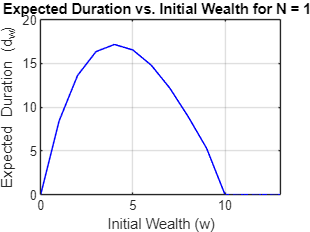

C1 =      2.723688032885887e+02


C2 =     -2.723688032885887e+02


C3 =      -6.370589360458413e-48 + 4.264980789838298e-47i


C4 =      -6.370589360458413e-48 - 4.264980789838298e-47i


C5 =     -1.772448698581105e-54


d_W = 1.0e+02 *

  -0.000000000000000
   0.580606504615952
   1.013247372317065
   1.332410175129998
   1.564544182073404
   1.729933912773086
   1.844136006475273
   1.919081188141745
   1.963919390213608
   1.985667894871532


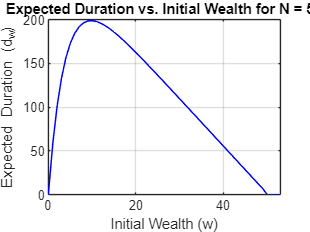

C1 =      5.434980641867603e+02


C2 =     -5.434980641867603e+02


C3 =       3.122727983122264e-93 - 1.306996260908299e-93i


C4 =       3.122727983122264e-93 + 1.306996260908299e-93i


C5 =    -7.987229252019429e-108


d_W = 1.0e+02 *

   0.000000000000000
   1.212549846916567
   2.129841807252901
   2.820694073139215
   3.337884812769616
   3.721890751145174
   4.003754368951971
   4.207282819736153
   4.350734327307264
   4.448111520582414


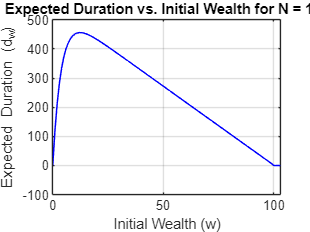


N_values = [10, 50, 100]; 
n = length(N_values);

for i = 1:n
    N = N_values(i);

    % Solve for coefficients
    syms c_1 c_2 c_3 c_4 c_5;
    [c_1, c_2, c_3, c_4 c_5] = solve( ...
        c_1*(l_1)^(0) + c_2*(l_2)^(0) + c_3*(l_3)^(0) + c_4*(l_4)^(0) + c_5*(l_5)^(0)- (0)/(4*p_4 + 3*p_3 + 2*p_2 + p_1 - q) == 0, ...
        c_1*(l_1)^(N) + c_2*(l_2)^(N) + c_3*(l_3)^(N) + c_4*(l_4)^(N) + c_5*(l_5)^(N)- (N)/(4*p_4 + 3*p_3 + 2*p_2 + p_1 - q) == 0, ...
        c_1*(l_1)^(N+1) + c_2*(l_2)^(N+1) + c_3*(l_3)^(N+1) + c_4*(l_4)^(N+1) + c_5*(l_5)^(N+1) - (N+1)/(4*p_4 + 3*p_3 + 2*p_2 + p_1 - q) == 0, ...
        c_1*(l_1)^(N+2) + c_2*(l_2)^(N+2) + c_3*(l_3)^(N+2) + c_4*(l_4)^(N+2) + c_5*(l_5)^(N+2) - (N+2)/(4*p_4 + 3*p_3 + 2*p_2 + p_1 - q) == 0, ...
        c_1*(l_1)^(N+3) + c_2*(l_2)^(N+3) + c_3*(l_3)^(N+3) + c_4*(l_4)^(N+3) + c_5*(l_5)^(N+3) - (N+3)/(4*p_4 + 3*p_3 + 2*p_2 + p_1 - q) == 0);

    C1 = double(c_1) % Extract values
    C2 = double(c_2)
    C3 = double(c_3)
    C4 = double(c_4)
    C5 = double(c_5)

    d_W = zeros(1, N+4);
    
    for W = 1:N+3
        d_W(W) = C1*(l_1)^(W-1) + C2*(l_2)^(W-1) + C3*(l_3)^(W-1) + C4*(l_4)^(W-1) + C5*(l_5)^(W-1) - (W-1)/(4*p_4 + 3*p_3 + 2*p_2 + p_1 - q) ;
    end

    d_W = double(d_W)'
    
    figure;
    plot(0:N+3, d_W, 'b', 'LineWidth', 1);
    xlabel('Initial Wealth (w)');
    ylabel('Expected Duration (d_w)');
    title(['Expected Duration vs. Initial Wealth for N = ', num2str(N)]);
    grid on;
    xlim([0 N+3])

end